#### Circuit classe E normalisé

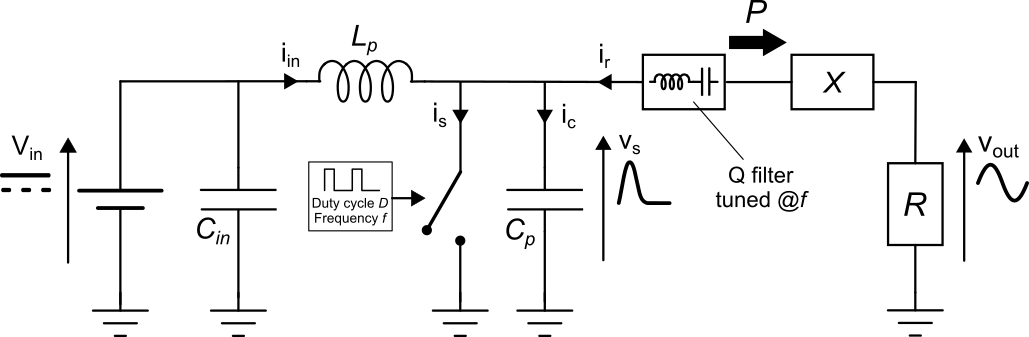

 

%D = round(linspace(0.18,0.72,109),5).';
D = round(linspace(0.01,0.99,99),5).';
D = 0.4;
q = round(linspace(0.001,3,800),5);
%q = round(linspace(0.001,2.401,699),5);
q = 1.2915; %q != 1

%One at a time
K = 0.5; % Norm. switch voltage at turn-on
zeta = -1; % Norm. switch voltage derivative at turn-on

 

%Calcul des coefficients a1,b1,c1,a2,b2,c2 (équations de continuité courant/tension)
a1 = q./(q.^2-1).*(cos(q*2*pi.*(D-1))-q.^2.*cos(2*pi*D)+(q.^2-1));
b1 = q./(q.^2-1).*(-q.*sin(q*2*pi.*(D-1))+(q.^2).*sin(2*pi*D));
c1 = 2*pi.*q.*D+(K-1)*sin(2*pi*q.*(D-1))+zeta./q.*(1-cos(2*pi*q.*(D-1)));
a2 = q./(q.^2-1).*(sin(q*2*pi.*(D-1))-q.*sin(2*pi*D));
b2 = q./(q.^2-1).*(q*cos(q*2*pi.*(D-1))-q.*cos(2*pi*D));
c2 = -(K-1)*cos(2*q*pi.*(D-1))-1-zeta./q.*sin(2*pi*q.*(D-1));

paramA = (b1.*c2-b2.*c1)./(a2.*b1-a1.*b2);
paramB = (a1.*c2-a2.*c1)./(a2.*b1-a1.*b2);
p = sqrt(paramA.^2+paramB.^2);
phi = atan2(paramA,paramB);

%Calculs des constantes vérifiant les conditions de commutation
k1 = p.*q./(1-q.^2).*(q.*cos(2*pi*q).*cos(phi)+sin(2*pi*q).*sin(phi))+(K-1)*cos(2*pi*q)-zeta./q.*sin(2*pi*q);
k2 = p.*q./(1-q.^2).*(q.*sin(2*pi*q).*cos(phi)-cos(2*pi*q).*sin(phi))+(K-1)*sin(2*pi*q)+zeta./q.*cos(2*pi*q);

%Calcul de gx
g = (pi*D.^2)./p-cos(2*pi*D+phi)/(2*pi)-D.*sin(phi)+cos(phi)/(2*pi)+D./q.^2./p*zeta;

%Calcul des coefficients de la FHA
X_q = 1./(q.^2-1).*(k1.*(cos(2*pi*q.*D).*sin(2*pi*D+phi)-cos(2*pi*q).*sin(phi)-q.*sin(2*pi*q.*D).*cos(2*pi*D+phi)+q.*sin(2*pi*q).*cos(phi)) ...
    +k2.*(sin(2*pi*q.*D).*sin(2*pi*D+phi)-sin(2*q*pi).*sin(phi)+q.*cos(2*pi*q.*D).*cos(2*pi*D+phi)-q.*cos(2*pi*q).*cos(phi)));
X_0 = sin(phi)-sin(2*pi*D+phi);
X_n = q.^2./(q.^2-1).*p/4.*(4*pi*(1-D)+sin(2*phi)-sin(4*pi*D+2*phi));
R_q = 1./(q.^2-1).*(k1.*(-cos(2*pi*q.*D).*cos(2*pi*D+phi)+cos(2*pi*q).*cos(phi)-q.*sin(2*pi*q.*D).*sin(2*pi*D+phi)+q.*sin(2*pi*q).*sin(phi)) ...
    +k2.*(-sin(2*pi*q.*D).*cos(2*pi*D+phi)+sin(2*pi*q).*cos(phi)+q.*cos(2*pi*q.*D).*sin(2*pi*D+phi)-q.*cos(2*pi*q).*sin(phi)));
R_0 = -cos(phi)+cos(2*pi*D+phi);
R_n = q.^2./(q.^2-1).*p/4.*(-cos(2*phi)+cos(4*pi*D+2*phi));

VX_norm = 1/pi*(X_q+X_0+X_n);
VR_norm = 1/pi*(R_q+R_0+R_n);
Vs_norm = sqrt(VX_norm.^2+VR_norm.^2);
psi = atan(VX_norm./VR_norm);


%Paramètres circuit normalisé (V, R, w)
L_norm = p/2./g;
C_norm = 2*g./p./q.^2;
X_norm = VX_norm./VR_norm;
P_norm = 2*g.^2;
Idc_norm = 2*g.^2;
Vout_norm = 2*g;
Rdc_norm = 1/2./g.^2;
Ir_norm = 2*g;



%Contraintes switch
Vsp_norm = (1.7613+0.05*q)./(1-D);
Isp_norm = 2*g.*(2*pi*D./p - sin(phi) + sin(2*pi*D+phi));
for Di = 1:length(D)
    for qi = 1:length(q)
        if ((p(Di,qi) >= 1) && (2*pi*D(Di)/p(Di,qi)+sin(2*pi*D(Di)+phi(Di,qi))-sin(acos(-1/p(Di,qi)))-(acos(-1/p(Di,qi))-phi(Di,qi))/p(Di,qi) <= 0) && (acos(-1/p(Di,qi))-phi(Di,qi)-2*pi*D(Di) <= 0))
            Isp_norm(Di,qi) = 2*g(Di,qi)*((acos(-1/p(Di,qi))-phi(Di,qi))/p(Di,qi)-sin(phi(Di,qi))+sin(acos(-1/p(Di,qi))));
        end
    end
end
IsRMS_norm = 2*g./p.*sqrt(8/6*pi^2*D.^3-2*pi*D.^2.*p.*sin(phi)+p.^2/pi.*sin(phi).*(cos(2*pi*D+phi)-cos(phi))-2*D.*p.*cos(2*pi*D+phi)-p.^2.*sin(4*pi*D+2*phi)./8/pi+p/pi.*sin(2*pi*D+phi)-D.*p.^2.*cos(2*phi)/2+D.*p.^2-p/pi.*sin(phi)+p.^2.*sin(2*phi)/8/pi);
cp = 2*g.^2./Vsp_norm./Isp_norm;
cpmr = 2*g.^2./Vsp_norm./IsRMS_norm;

 

f = 6.78e6;
R = 29;
V = 30;

w = 2*pi*f;

L = L_norm*R/w;
C = C_norm/R/w;
X = X_norm*R;
P = P_norm*V^2/R;
Idc = Idc_norm*V/R;
Vout = Vout_norm*V;
Rdc = Rdc_norm*R;
Ir = Ir_norm*V/R;
Vsn = Vs_norm*V;
VRn = VR_norm*V;
VXn = VX_norm*V;
Vsp = Vsp_norm*V;
Isp = Isp_norm*V/R;
IsRMS = IsRMS_norm*V/R;

#### UNE FOIS QUE q et D ONT ETE FIXES ! (ça marche avec zeta et K ?)

  
%(Vin = 1 V, R = 1 Ohm, w = 1 rad/s)

T = 2*pi;
nperiodes = 1;
npoints_periode = 2000;  %even number
fsample = npoints_periode/2/pi;
Tsample = 1/fsample;
npoints = nperiodes*npoints_periode;
t = (0:npoints-1)*Tsample;

%Tensions

vs = k1*cos(q*t)+k2*sin(q*t)+1+q^2/(q^2-1)*p*cos(t+phi);
vs(t<(D*T))=0;

vs1 = VR_norm*sin(t+phi)+VX_norm*cos(t+phi);

vout = -2*g*sin(t+phi);


%Courants

ir = 2*g*sin(t+phi);

iin = 2*g/p*(t-p*sin(phi)+zeta/q^2);
iin(t>(D*T)) = 2*g/p/q*(-k1*sin(q*t(t>(D*T)))+k2*cos(q*t(t>(D*T)))-p*q^3/(q^2-1)*sin(t(t>(D*T))+phi));

is = iin+ir;
is(t>(D*T)) = 0;

ic = iin+ir; 
ic(t<(D*T))=0;
